# Materials classification - A1

clc; clear all; close all;

## Import dataset

image_data_folder = "Data\Train\image\";
mask_data_folder = "Data\Train\mask\";
image = Images_import(image_data_folder);
mask = Images_import(mask_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood

## Create targets

for idx = 1:length(image)
    if contains(image(idx).path, "fabric")
        image(idx).target = "fabric";
        mask(idx).target = "fabric";
    elseif contains(image(idx).path, "foliage")
        image(idx).target = "foliage";
        mask(idx).target = "foliage";
    elseif contains(image(idx).path, "glass")
        image(idx).target = "glass";
        mask(idx).target = "glass";
    elseif contains(image(idx).path, "leather")
        image(idx).target = "leather";
        mask(idx).target = "leather";
    elseif contains(image(idx).path, "metal")
        image(idx).target = "metal";
        mask(idx).target = "metal";
    elseif contains(image(idx).path, "paper")
        image(idx).target = "paper";
        mask(idx).target = "paper";
    elseif contains(image(idx).path, "plastic")
        image(idx).target = "plastic";
        mask(idx).target = "plastic";
    elseif contains(image(idx).path, "stone")
        image(idx).target = "stone";
        mask(idx).target = "stone";
    elseif contains(image(idx).path, "water")
        image(idx).target = "water";
        mask(idx).target = "water";
    elseif contains(image(idx).path, "wood")
        image(idx).target = "wood";
        mask(idx).target = "wood";
    end
end

### Create image set

% Apply the mask and save only the foreground object
% reqSize = 30;   % Size of the image patch for subsequent analysis and model training
imgData = [];
for idx = 1:length(image)
    tempImg = imread(image(idx).path);
    tempMask = imread(mask(idx).path);
    tempImg(~tempMask) = 0;
    imgData{idx} = tempImg;
end

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];

## Feature Extraction

### Feature 1: Entropy measure

entropyVals = [];
for idx = 1:length(imgData)
    entropyVals(idx) = entropy(double(im2gray(imgData{idx}(:))));
end
save("entropyVals.mat", "entropyVals");

### Feature 2: Number of edges

edgeCount = [];
for idx = 1:length(imgData)
    bw = edge(im2gray(imgData{idx}),'canny');
    edgeCount(idx) = nnz(bw);
end

save("edgeCount.mat", "edgeCount");

### Feature 3: Std. deviation of image

for idx = 1:length(imgData)
    imgDev(idx) = std(double(im2gray(imgData{idx}(:))));
end
save("imgDev.mat", "imgDev");

### Feature 4: Mean of RGB 

imgMean = [];
for idx = 1:length(imgData)
    a = double(imgData{idx});
    imgMean(idx, :) = mean(reshape(a, [], 3, 1));
end

imgMean = imgMean';
save("imgMean.mat", "imgMean");

### Feature 5: HOG features 

for idx = 1:length(imgData)
    imgHog(idx,1) = sum(extractHOGFeatures(imgData{idx}));
    imgHog(idx,2) = max(extractHOGFeatures(imgData{idx}));
    imgHog(idx,3) = mean(extractHOGFeatures(imgData{idx}));
end

imgHog = imgHog';
save("imgHog.mat", "imgHog");

### Feature 6: SURF features 

for idx = 1:length(imgData)
    points = detectSURFFeatures(im2gray(imgData{idx}));
    if size(points,1) == 0
        imgSURF(idx,1) = 0;
        imgSURF(idx,2) = 0;
        imgSURF(idx,3) = 0;
    else
        imgSURF(idx,1) = sum(sum(extractFeatures(im2gray(imgData{idx}),points)));
        imgSURF(idx,2) = max(max(extractFeatures(im2gray(imgData{idx}),points)));
        imgSURF(idx,3) = mean(mean(extractFeatures(im2gray(imgData{idx}),points)));
    end
end

imgSURF = imgSURF';
save("imgSURF.mat", "imgSURF");

### Feature 7: Number of objects 

for idx = 1:length(imgData)
    imgEuler(idx) = bweuler(im2bw(imgData{idx}));
end

save("imgEuler.mat", "imgEuler");

## Dividing the variables that need discretization

clc; clear all; close all;

rng('default')

load edgeCount.mat
load entropyVals.mat
load imgDev.mat
load imgHog.mat
load imgMean.mat
load imgEuler.mat
load imgSURF.mat

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];
features = [edgeCount; entropyVals; imgDev; imgHog; imgMean; imgSURF; imgEuler]';

nseg = 4;
data = features;
% append new column class, represented for every 90 sequential obs
classCount = 1;
for idx = 1:length(data)
    data(idx,size(features,2) + 1) = classCount;
    if mod(idx,90) == 0
        classCount = classCount + 1;
    end
end

for i = 1:length(data(1,1:end-1))

    var     = data(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(data(:,i)>=seg(ii).LB), find(data(:,i)<seg(ii+1).LB));
        data2(idxCurrent,i) = ii;
    end

    idxCurrent = find(data(:,i)>seg(ii+1).LB);
    data2(idxCurrent,i) = ii+1;
end

data2(:,end+1) = data(:,end);


## Data Division

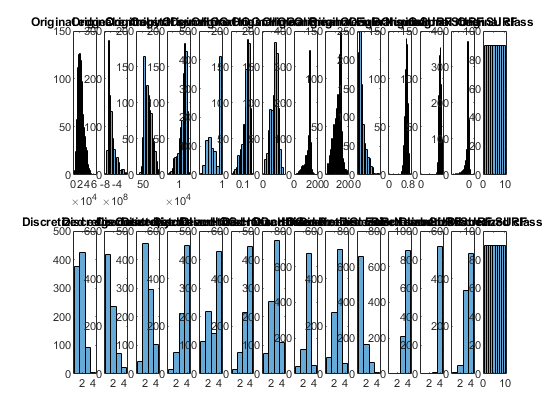

[row, col]      = size(data2);
varLabels = ["edgeCount", "entropy", "stdDev", "sumHOG", "maxHOG", "meanHOG", "meanR", "meanG", "meanB", "EulerNumber", "sumSURF", "maxSURF", "meanSURF", "class"];

ii = 1;
for i = 1:col
    subplot(2, col, i);
    histogram(data(:,i)); title("Original " + varLabels(i));

    subplot(2, col, i+col);
    histogram(data2(:,i)); title("Discretized " + varLabels(i));
end

% Test and calibration in the partition below.
partitionRatio = 0.1;
c       = cvpartition(data(:,end), 'Holdout', partitionRatio);
idxCal = test(c);
idxTrain  = training(c);

dataAll  = data2;
dataTrain    = dataAll(idxTrain,  :);
dataCal = dataAll(idxCal, :);


## Learn the structure of a BN

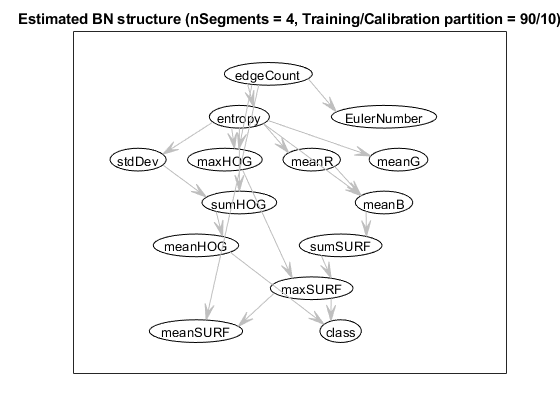

[row, col]      = size(dataTrain);

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(dataTrain');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(dataTrain(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 2, 'verbose', 'no');
BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end

figure;
draw_graph(BNhat.dag, varLabels);
title(sprintf("Estimated BN structure (nSegments = %d, Training/Calibration partition = %d/%d)", nseg, 100-partitionRatio*100, partitionRatio*100));

## Training

engine       = global_joint_inf_engine(BNhat);

[rowT, colT] = size(dataCal);

for j = 1:rowT
    evidence     = [];
    evidence     = cell(1,colT);
    
    for i = 1:col-1
        evidence{variable(i).node} = dataCal(j,i);
    end
    [engine, logLikelihood] = enter_evidence(engine, evidence);
    marginal       = marginal_nodes(engine, variable(end).node);
    totProb        = sum(marginal.T(:));
    dataPoint(j).M = marginal.T ./ totProb;
    [~, dataPoint(j).yhat] = max(dataPoint(j).M);
end

Index in position 2 exceeds array bounds (must not exceed 3).

Error in discrete_CPD/convert_to_table (line 14)
T = CPT(index{:});

Error in discrete_CPD/convert_to_pot (line 2


Ypred = categorical([dataPoint.yhat]');
Ytrue = categorical(dataCal(:,end));

accuracy = sum(Ypred==Ytrue)/length(Ytrue);
ACCURACY_CAL(nseg,nseg) = accuracy;
figure;
cm = confusionmat(Ytrue, Ypred);
results = confusionchart(cm, inputs, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
results.title(sprintf("Confusion chart (nSegments = %d, Training/Calibration partition = %d/%d) ACCURACY = %0.2f%%", nseg, 100-partitionRatio*100, partitionRatio*100, accuracy*100));

## Naive Bayes classifier

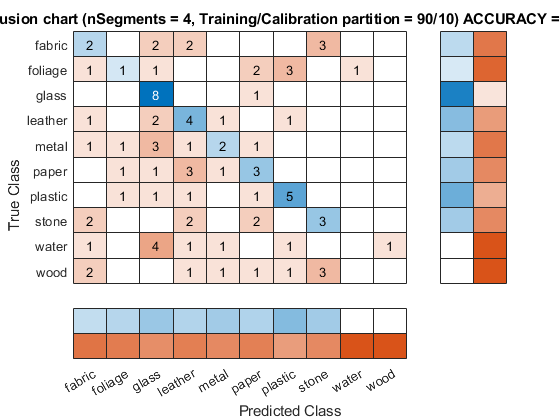

dataAll  = data;
dataTrain    = dataAll(idxTrain,  :);
dataCal = dataAll(idxCal, :);

Mdl = fitcnb(dataTrain(:,1:end-1), dataTrain(:,end));

label = predict(Mdl, dataCal(:,1:end-1));
Ypred = categorical(label);
Ytrue = categorical(dataCal(:,end));

accuracy = sum(Ypred==Ytrue)/length(Ytrue);
ACCURACY_CAL(nseg,nseg) = accuracy;
figure;
cm = confusionmat(Ytrue, Ypred);
results = confusionchart(cm, inputs, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
results.title(sprintf("Confusion chart (nSegments = %d, Training/Calibration partition = %d/%d) ACCURACY = %0.2f%%", nseg, 100-partitionRatio*100, partitionRatio*100, accuracy*100));